% Format NDVI 

% This script formats and saves NDVI from 8/2017 to 12/2021 as a .mat file
clear;
% 

addpath MDG_adm_4/;
addpath m_map/;
addpath mdg_adm_bngrc_ocha_20181031_shp/;
addpath Final_Scripts/cameri/
% 
% % filename = 'S_Madagascar_NDVI_250m_2017_2022.mat'
% 
% ncdisp(filename);
% % 
% 
% ndvi_lat = ncread(filename,'lat');
% ndvi_lon = ncread(filename,'lon');
% ndvi_time = ncread(filename,'time');
% ndvi = ncread(filename,'_250m_16_days_NDVI');
% 
% ndvi_time = double(ndvi_time)+datenum(2000,1,1);
% [year, month, day] = datevec(double(ndvi_time));
% 
% imagesc(ndvi(:,:,1))
% 
% ndvi = permute(ndvi,[2 1 3]);


load S_Madagascar_NDVI_250m_2000_2022.mat

good_jet = crameri('batlow')

good_jet =     0.0036    0.1000    0.3501
    0.0059    0.1041    0.3508
    0.0082    0.1082    0.3515
    0.0105    0.1124    0.3522
    0.0129    0.1164    0.3529
    0.0150    0.1204    0.3536
    0.0171    0.1245    0.3543
    0.0191    0.1285    0.3550
    0.0211    0.1326    0.3557
    0.0231    0.1366    0.3564
    0.0250    0.1406    0.3571
    0.0269    0.1446    0.3578
    0.0287    0.1486    0.3584
    0.0305    0.1526    0.3591
    0.0323    0.1566    0.3598


load district_centroids.mat

[year, month, day] = datevec(double(ndvi_time));

% % Limit time 
tidx = find(year <= 2017);

ndvi_filtered= ndvi(:,:,tidx);


% % filtered ndvi mean 
mean_ndvi_filtered = mean(ndvi_filtered,3)

mean_ndvi_filtered =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   N

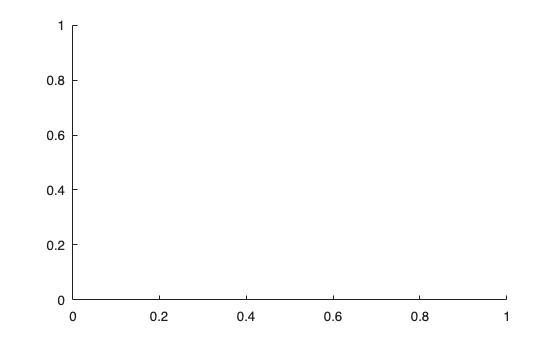


madagascar = shaperead('mdg_admbnda_adm3_BNGRC_OCHA_20181031');

figure(3); clf; hold on;

figure('Units','inches','Position',[1 1 8 6.5]); % [x y width height]
m_proj('miller','lon',[44.4 45.9],'lat',[-25.65 -24.9]);
m_pcolor(ndvi_lon,ndvi_lat,mean_ndvi_filtered);
m_grid('linestyle','none','tickdir','out','linewidth',2,'fontsize',18);
caxis([0 1]);

    
    M=m_shaperead('mdg_admbnda_adm3_BNGRC_OCHA_20181031'); 

1579 Records in file, by 500:
---
...

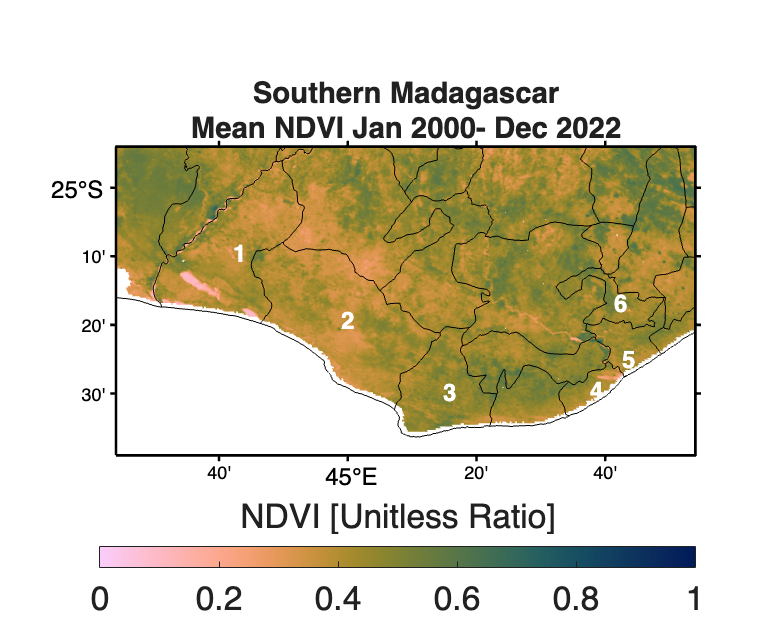


    
    for k=1:length(M.ncst), 
         m_line(M.ncst{k}(:,1),M.ncst{k}(:,2),'Color','black'); 
    end;

   
        h = colorbar('southoutside');
    cmap = crameri('-batlow');
    colormap(repelem(cmap, 26, 1));
    % Set colorbar title
    h.Title.String = "NDVI [Unitless Ratio]";
    h.Position(2) = h.Position(2) - 0.15;  % move it down
    % % Move title down (closer to colorbar, away from main plot)
    % h.Title.Position(2) = -5;  % Try values like -1, -2, or -3 depending on how low you want




    % % District Numbers 
        m_text(district_centroids(1,1),district_centroids(1,2),52.5,'2','color','w','fontweight','bold','fontsize',18); %Tranovaho
        m_text(district_centroids(2,1),district_centroids(2,2),52.5,'1','color','w','fontweight','bold','fontsize',18); %Marolinta
        m_text(district_centroids(5,1),district_centroids(5,2),52.5,'4','color','w','fontweight','bold','fontsize',18); %Anjampaly
        m_text(district_centroids(6,1),district_centroids(6,2),52.5,'3','color','w','fontweight','bold','fontsize',18); %Morovato
        m_text(district_centroids(7,1)-0.02,district_centroids(7,2)-0.04,52.5,'5','color','w','fontweight','bold','fontsize',18); %Antaritarika
        m_text(district_centroids(8,1),district_centroids(8,2),52.5,'6','color','w','fontweight','bold','fontsize',18); %Imongy



set(gca, 'FontSize', 28,'LineWidth',1.5);
title({'Southern Madagascar','Mean NDVI Jan 2000- Dec 2022'},'FontSize',22)

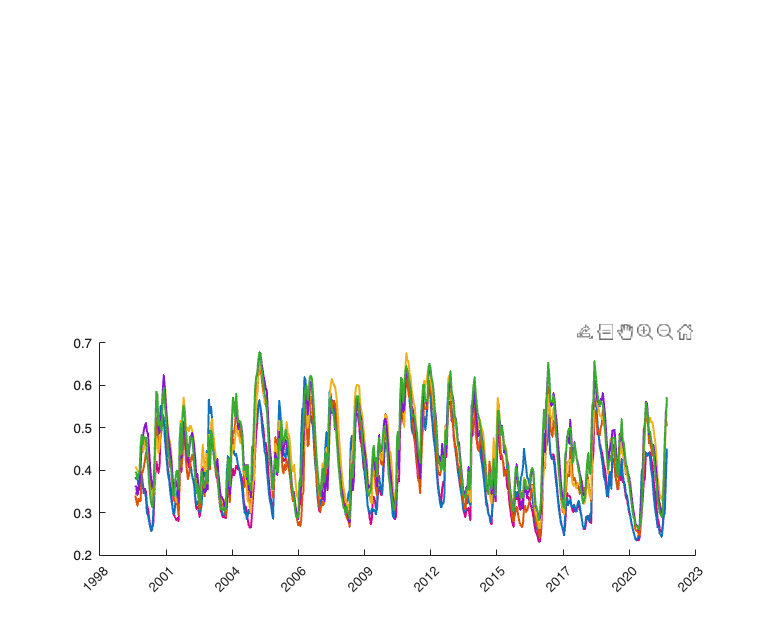

% Add time series

load mira_communes.mat
load d1_ndvi_ts.mat
load d2_ndvi_ts.mat
load d5_ndvi_ts.mat
load d6_ndvi_ts.mat
load d7_ndvi_ts.mat
load d8_ndvi_ts.mat

hold on;
dn_idx = [1 2 5 6 7 8];

% dist_labels = table2array(mira_district_names(dn_idx,:))
subplot(2,1,2)
hold on;
plot(ndvi_time,mean_d1_ndvi,"Linewidth",1.5);
hold on;
plot(ndvi_time,mean_d2_ndvi,"Linewidth",1.5);
hold on;
plot(ndvi_time,mean_d5_ndvi,"Linewidth",1.5);
hold on;
plot(ndvi_time,mean_d6_ndvi,"Linewidth",1.5);
hold on;
plot(ndvi_time,mean_d7_ndvi,"Linewidth",1.5);
hold on;
plot(ndvi_time,mean_d8_ndvi,"Linewidth",1.5);
datetick('x','yyyy','keepticks'); % Display only the year


ax = gca;
ax.XTickLabelRotation = 45; 


legend(dist_labels,'Fontsize',14,"Location","bestoutside");

Unrecognized function or variable 'dist_labels'.

% title("Mean NDVI by District","FontSize",24);
xlabel("Year [C.E.]","FontSize",18);
ylabel("NDVI [Unitless Ratio]","FontSize",18)
ax = gca;
set(ax, 'FontSize', 28,'LineWidth',1.5);





